%plot on z
% Define constants
q = 2*pi;
%q=1;
%epsilon_0 = 8.854187817e-12; % Vacuum permittivity
epsilon_0 = 1e-2; % Vacuum permittivity
epsilon_r = 2; % Relative permittivity

q_volume=q / (2 * pi * epsilon_0 * epsilon_r)

q_volume = 50.0000

q_surface=(q_volume * (epsilon_r-1)/ (epsilon_r + 1))

q_surface = 16.6667

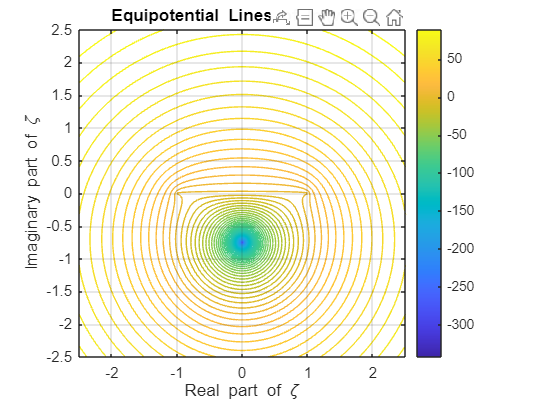




f_left=@(zeta) (zeta-sqrt(zeta.^2-1)) ;
f_right=@(zeta) (zeta+sqrt(zeta.^2-1)) ;


wright=@(z) i*(q_volume+q_surface)*(log(z+sqrt(z.^2-1)+i*2)-log(1./(z+sqrt(z.^2-1))-i*2));
wleft=@(z) i*(q_volume+q_surface)*(log(z-sqrt(z.^2-1)+i*2)-log(1./(z-sqrt(z.^2-1))-i*2));

%w_up=@(zeta) i*(q_volume+q_surface)*log(zeta+i*2)-i*log(1./(zeta)-i*2);
% 定义网格的范围和分辨率
x = linspace(-2.5, 2.5, 600);
y = linspace(-2.5, 2.5, 600);
[X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;

% 计算 w(zeta) 的值
W_grid_left = wleft(z_grid);
W_grid_right = wright(z_grid);

%
W_grid = zeros(size(X));

% Apply V_lower for y < 0 and V_upper for y > 0

W_grid(X > 0) = W_grid_right(X > 0); % 使用逻辑条件来选择相应的区域
W_grid(X < 0) = W_grid_left(X < 0);


% 提取实部和虚部
W_real = real(W_grid);
W_imag = imag(W_grid);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 80);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;

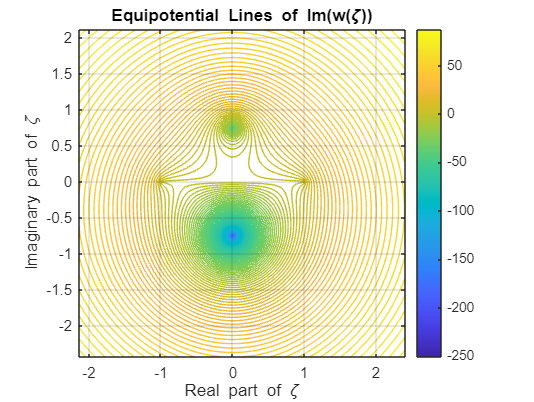

 x = linspace(-2.5, 2.5, 600);
 y = linspace(-2.5, 2.5, 600);
 [X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;


w_down_right=@(z) i*(q_volume)*( log(z+sqrt(z.^2-1)+i*2)-log(1./(z+sqrt(z.^2-1))-i*2) )+ i*(q_surface)*( log(z+sqrt(z.^2-1)-i*2)-log(1./(z+sqrt(z.^2-1))+i*2));
w_down_left=@(z) i*(q_volume)*( log(z-sqrt(z.^2-1)+i*2)-log(1./(z-sqrt(z.^2-1))-i*2) ) + i*(q_surface)*( log(z-sqrt(z.^2-1)-i*2)-log(1./(z-sqrt(z.^2-1))+i*2));


W_lower_grid_right = w_down_right(z_grid);
W_lower_grid_left = w_down_left(z_grid);


W_lower_grid(X>0) = W_lower_grid_right(X>0);

W_lower_grid(X<0) = W_lower_grid_left (X<0);


W_real = real(W_lower_grid);
W_imag = imag(W_lower_grid);

figure;
contour(X, Y, W_imag, 150);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;

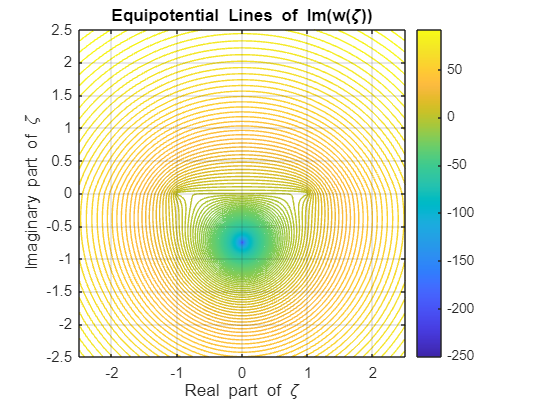

%plot on z
% % Define the range for x and y
 x = linspace(-2.5, 2.5, 600);
 y = linspace(-2.5, 2.5, 600);
 [X, Y] = meshgrid(x, y);
z_grid = X + 1i * Y;
% Define the potential functions

% 计算 w(zeta) 的值

%
whole_map = zeros(size(X));


whole_map(Y <= 0.) = W_lower_grid(Y <= 0.);%W_map_lower(X < 0); % 使用逻辑条件来选择相应的区域
whole_map(Y >= 0.) = W_grid(Y >= 0.);

% 提取实部和虚部
W_real = real(whole_map);
W_imag = imag(whole_map);

% 绘制等势线图
figure;
contour(X, Y, W_imag, 150);  % 50 是等高线的数量
xlabel('Real part of \zeta');
ylabel('Imaginary part of \zeta');
title('Equipotential Lines of Im(w(\zeta))');
colorbar;
axis equal;
grid on;